% 16-714 Advanced Control for Robotics
% extra credit
% Yutong Huang
clc;clear;
close all;

% assuming C = 1 * ones(14,1) (full state)
% and the disturbances W on the control U that is N(0,0.01)
% and the disturbances V on the obs C that is N(0,0.0001)

## Initialization

global robot;
robot = loadrobot('kinovaGen3','DataFormat','row','Gravity',[0 0 -9.81]);

goal = [0.4, 0, 0.6];
x0 = homeConfiguration(robot);
x0 = [x0'; zeros(7,1)];
endEffector = "EndEffector_Link";
taskInit = getTransform(robot, x0(1:7)', endEffector);
taskFinal = trvec2tform(goal) * axang2tform([0 1 0 pi]);
ik = inverseKinematics("RigidBodyTree", robot);
xT = ik(endEffector, taskFinal, [1 1 1 1 1 1], x0(1:7)');
xT = mod(xT, 2*pi);
xT = [xT'; zeros(7,1)];

Tmax = 5;
dt = 0.05;


## Extended System Matrices for all 7 joints together

nx = 14; % 7 pos + 7 vel
nu = 7;
A = 0.5*[eye(7), dt*eye(7); zeros(7), eye(7)];
B = 0.5*[zeros(7), dt*eye(7)]';

A_ref = [eye(7), dt*eye(7); zeros(7), eye(7)];
B_ref = [zeros(7), dt*eye(7)]';
% Cost weights
Q = blkdiag(1*eye(7), 1*eye(7)); % State cost weights
R = eye(nu);  % Correct dimension for control input

% Solve Discrete Algebraic Riccati Equation for LQR
[K_star, ~] = dlqr(A_ref, B_ref, Q, R)

K_star =     0.9576   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    1.7071    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
   -0.0000    0.9576   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    1.7071    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000    0.9576    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    1.7071    0.0000   -0.0000   -0.0000   -0.0000
   -0.0000    0.0000   -0.0000    0.9576    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    1.7071    0.0000    0.0000   -0.0000
   -0.0000    0.0000    0.0000    0.0000    0.9576    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    1.7071    0.0000   -0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.9576   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    1.7071   -0.0000
   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.9576   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    1.7071


A_star = A_ref - B_ref*K_star

A_star =     1.0000         0         0         0         0         0         0    0.0500         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0    0.0500         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0    0.0500         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0         0    0.0500         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0    0.0500         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0    0.0500         0
         0         0         0         0         0         0    1.0000         0         0         0         0         0         0    0.0500
   -

## Joint space control Rollout (MRAC)

u = @(x, k) -k * (x - xT);
f = @(x, u) A * x + B * u;
f_ref = @(x, u) A_ref * x + B_ref * u;

% Simulate Trajectory with Kalman Filter
tlist = 0:dt:Tmax;
Nsteps = length(tlist)-1;
xlist = zeros(size(x0,1), Nsteps+1);
xlist(:,1) = x0; 
x = x0;
x_ref = x0;
x_ref_list = zeros(size(x0,1), Nsteps+1);
x_ref_list(:,1) = x_ref;

C = [A, B];
F = 0.01 * eye(nx+nu);

ulist = zeros(size(u(x0, K_star),1), Nsteps);
elist = zeros(nx, Nsteps+1);
Clist = zeros(nx, nx+nu, Nsteps+1);
Clist(:,:,1) = C;
% Rollout
for k = 1:Nsteps
    % find A and B using current C
    A_est = C(:, 1:nx);
    B_est = C(:, nx+1:end);

    % find control gain
    K = pinv(B_est' * B_est) * (B_est' * (A_est - A_star));
    u_curr = u(x_ref, K);

    % Tracking error
    e = x_ref - x;
    phi = [x; u_curr];
    F = pinv(pinv(F) + phi * phi');

    update_term = e * (phi' * F); 
    C = C + update_term;

    x = (A_est - B_est*K)*(x-xT);

    x_ref = A_ref*x_ref + B_ref*u_curr;

    % Store trajectories
    xlist(:,k+1) = x;
    x_ref_list(:,k+1) = x_ref;
    ulist(:,k+1) = u_curr;
    elist(:,k+1) = e;
    Clist(:,:,k+1) = C;
end


## visualize

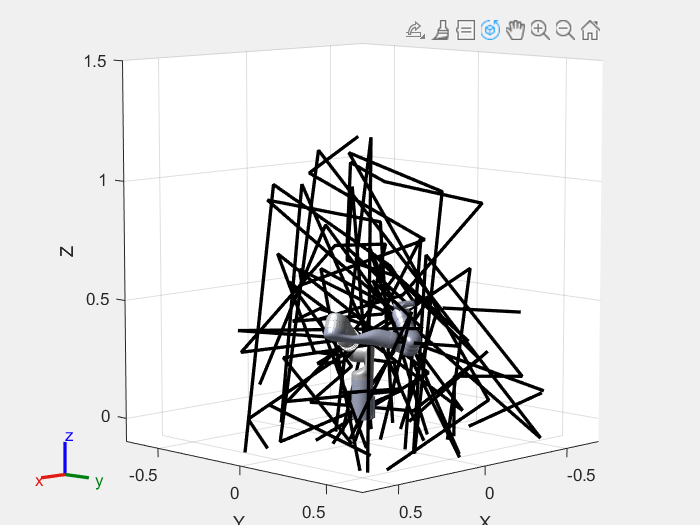

visualize_arm = 0;
figure(1); 
clist = zeros(length(tform2trvec(taskInit)),length(tlist)); 
clist(:,1) = tform2trvec(taskInit)';
for k = 2:length(tlist)
    x = xlist(1:7,k)';
    if visualize_arm
        pause(dt);
        show(robot,x,'PreservePlot',true,'Frames','off');
        axis([-0.7 0.7 -0.7 0.7 -0.1 1.5]);
    end
    clist(:,k) = tform2trvec(getTransform(robot,x,endEffector))';
end
show(robot,x,'PreservePlot',true,'Frames','off');
axis([-0.7 0.7 -0.7 0.7 -0.1 1.5]);
hold on;
plot3(clist(1,:),clist(2,:),clist(3,:),'k','LineWidth',2);
hold on;

## plot control tarj

% figure(2);
% subplot(3,1,1)
% plot(2:length(tlist), ulist,'LineWidth',2);
% title("control")
% xlim([0 100])
% subplot(3,1,2)
% plot(1:length(tlist), xlist(1:7,:),'LineWidth',2);
% title("joint position")
% xlim([0 100])
% subplot(3,1,3)
% plot(1:length(tlist), xlist(8:end,:),'LineWidth',2); 
% title("joint volecity")
% xlim([0 100])
